
clear
load("E:\Result\327\超声\KYM_0327_80_11s_final_M1L1T1_1.mat")

roi=final.Roi;
nummu=final.num_mu;
for i=1:nummu
    position(i,:)=getposition(roi(i),15,25);
end

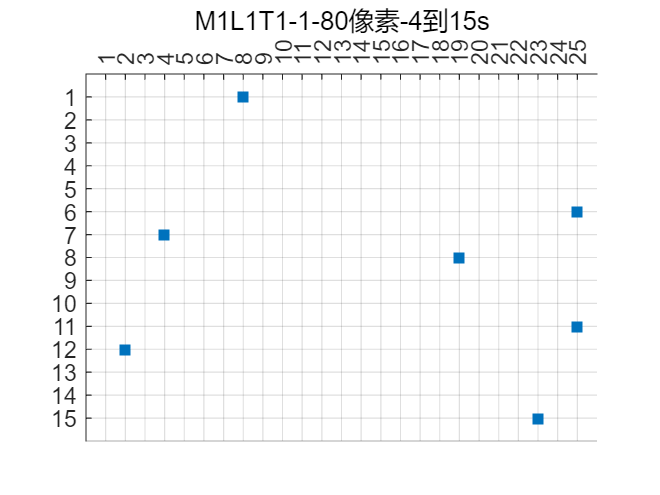

scatter(position(:,2),position(:,1),"filled",'square')
xticks(1:1:25);
yticks(1:1:15);
xlim([0 26])
ylim([0 16])
grid on
set(gca,'xaxislocation','top','YAxisLocation','left','ydir','reverse' )
title('M1L1T1-1-80像素-4到15s')

function [pos]=getposition(roi,lengthx,lengthy)
pos=[0;1];%最左边是第一行
while roi>lengthx
    roi=roi-lengthx;
    pos(2)=pos(2)+1;
end
pos(1)=roi;
end